x0 = -6;
y0 = -6;
x1 = 6;
y1 = 6;

paso = 1;
[xGrid, yGrid] = meshgrid(x0:paso:x1, y0:paso:y1);

Lamina Positiva:

rojo = [1, 0, 0];
posXLaminaP = -3;
posYLaminaP = -3;
anchoLaminaP = 1;
altoLaminaP = 6;

Lamina Negativa:

azul = [0 0 1];
posXLaminaN = 2;
posYLaminaN = -3;
anchoLaminaN = 1;
altoLaminaN = 6;

Campo Electrico:

Qp = 2; % Coulomb
Qn = -2; % Coulomb
k = 8.99e9; % Nm^2 / C^2

Rxn = xGrid - posXLaminaN; % Obtenemos todos los puntos en X
Ryn = yGrid ; % Obtenemos todos los puntos en Y

Rxp = xGrid - posXLaminaP; % Obtenemos todos los puntos en X
Ryp = yGrid ; % Obtenemos todos los puntos en Y

Rn = sqrt(Rxn.^2 + Ryn.^2).^2;
Rp = sqrt(Rxp.^2 + Ryp.^2).^2;

Ex = k .* Qn .* Rxn ./ Rn; % Se calcula el campo magnetico en cada punto en X
Ey = k .* Qn .* Ryn ./ Rn; % Se calcula el campo magnetico en cada punto en Y

Ex = Ex + k .* Qp .* Rxp ./ Rp; % Se calcula el campo magnetico en cada punto en X
Ey = Ey + k .* Qp .* Ryp ./ Rp; % Se calcula el campo magnetico en cada punto en Y

E = sqrt(((Ex).^2) + ((Ey).^2));

i = (Ex) ./ E;

j = (Ey) ./ E;

h = quiver(xGrid, yGrid, i, j);

Dibujar Laminas:

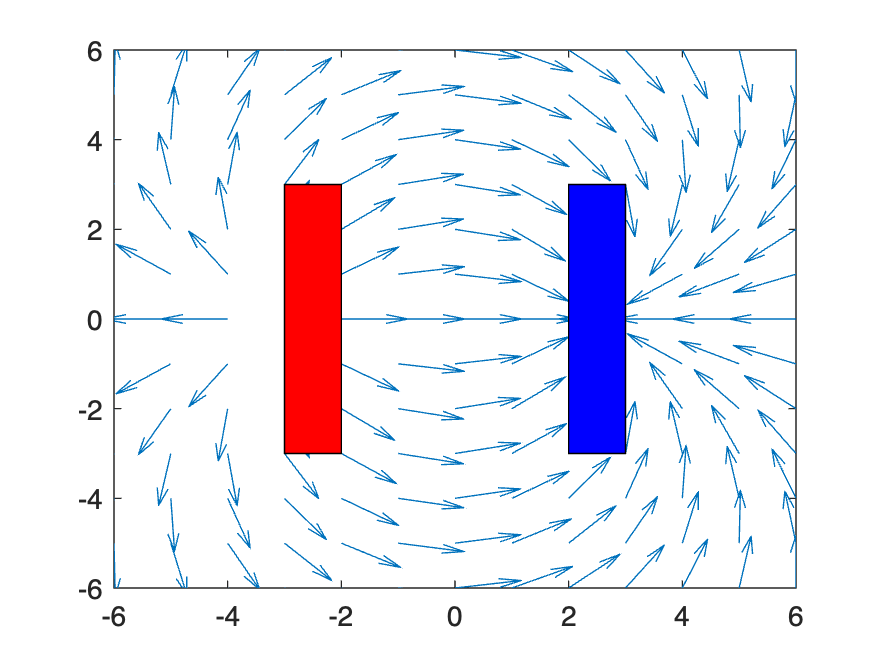

% Positiva
LaminaP = rectangle('Position', [posXLaminaP, posYLaminaP, anchoLaminaP, altoLaminaP]);
set(LaminaP, 'FaceColor', rojo);

% Negativa
LaminaN = rectangle('Position', [posXLaminaN, posYLaminaN, anchoLaminaN, altoLaminaN]);
set(LaminaN, 'FaceColor', azul);

axis([-6,6,-6,6])

%plot(xGrid, yGrid, 'k.')